clear; clc; close all;
% load the data
load ml_data

% Remove the SPGScore variable : 
ml_data(:,'SPGScore') = [];

% Scale the data; Normalize it; use zscore
ml_data{:, 2:end} = zscore(ml_data{:,2:end});

% Split the data into training and test sets
% Create the cvpartition variable
pt = cvpartition(ml_data.SPGGrade, 'HoldOut', 0.25);

% Create the training and test tables
nc_train = ml_data(training(pt), :);
nc_test = ml_data(test(pt), :);

% set random seed.
rng(1);

Mdl_TB = TreeBagger(...
    100,nc_train,'SPGGrade',...
    'Method','classification',...
    'Surrogate','on',...
    'PredictorSelection','curvature',...
    'OOBPredictorImportance','on'...
    );

% Use model to predict Wine Class
outputs=predict(Mdl_TB,nc_test);

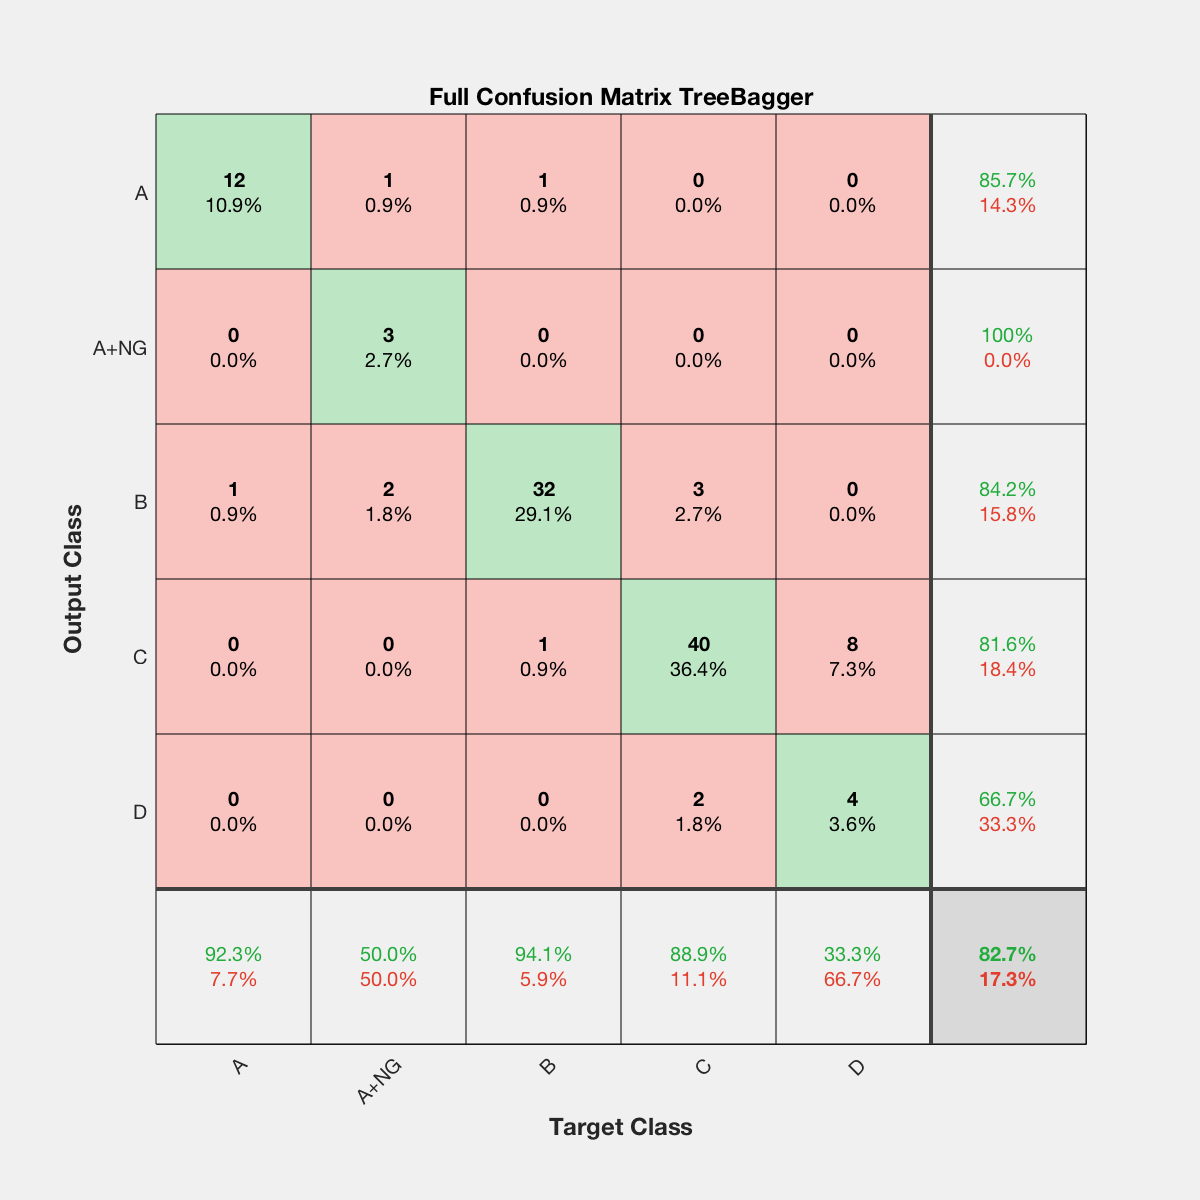

%--------------------------------------------------------------------------
% plot confusion matrix
figure
plotconfusion(categorical(nc_test.SPGGrade),categorical(outputs))
title('Full Confusion Matrix TreeBagger')
print('-dpng','NC-full-TreeBagger-ConfusionMatrix.png');% save to an png file

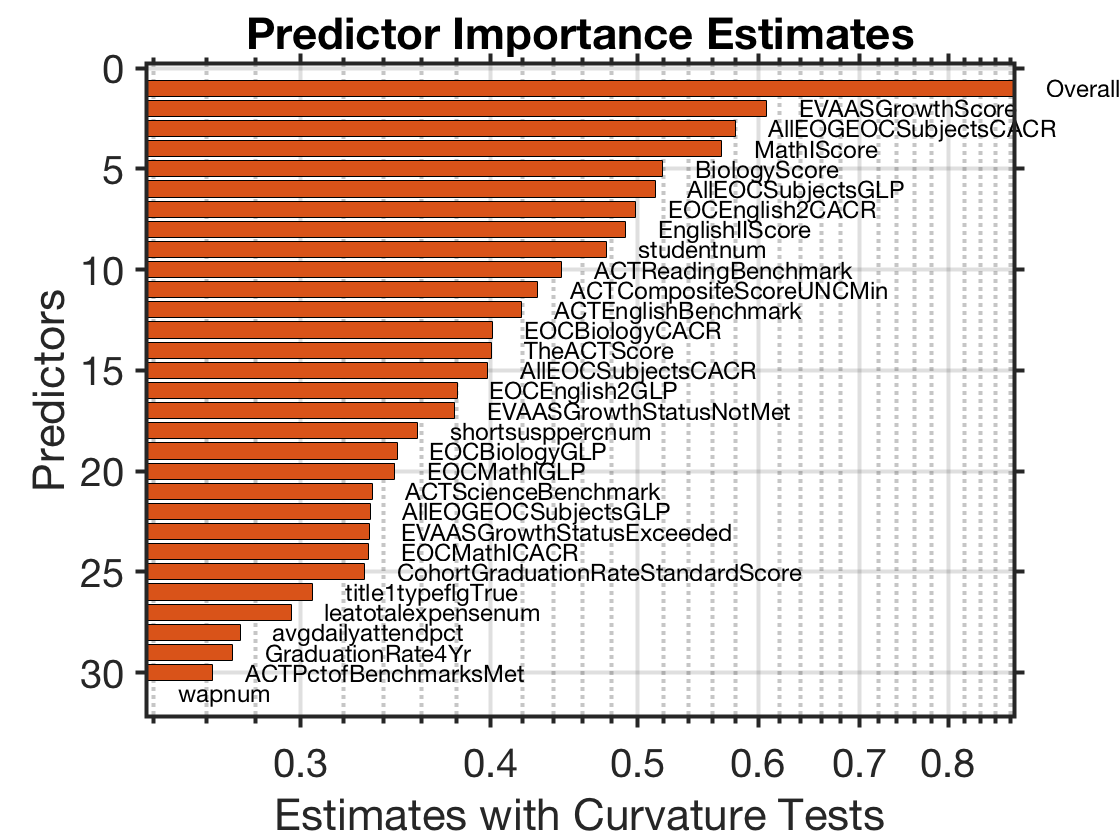

%--------------------------------------------------------------------------
% Estimate the predictor importance
imp=Mdl_TB.OOBPermutedPredictorDeltaError;
[sorted_imp,isorted_imp] = sort(imp,'descend');  

n = sum(imp>0);
if n  > 31
    n = 31;
end
barh(imp(isorted_imp(1:n)))

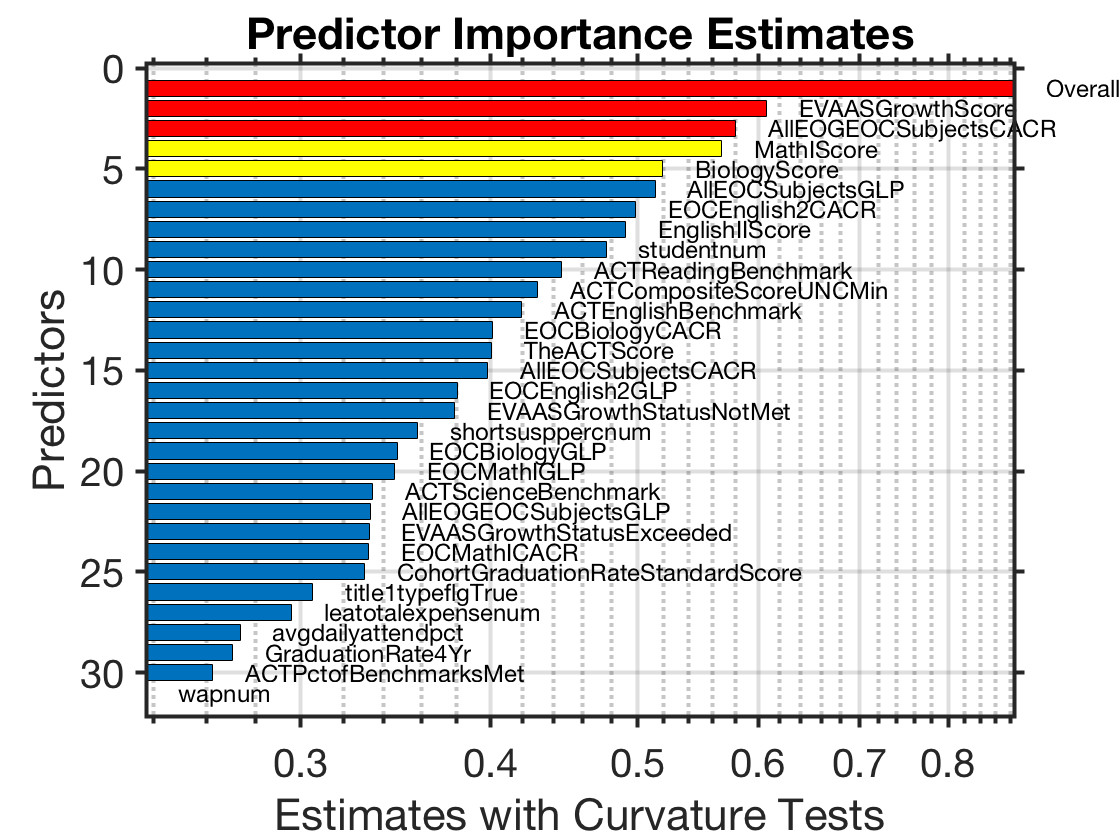


%--------------------------------------------------------------------------
% Draw a horizontal bar chart showing the variables in descending order of
% importance. Hint: look up the function barh.
% Label each variable with its name. 
% Hints: (1) Look up the function text. (2) Variable names are held in 
% Mdl.PredictorNames
figure;barh(imp(isorted_imp(1:n)));hold on;grid on;
barh(imp(isorted_imp(1:5)),'y');barh(imp(isorted_imp(1:3)),'r');
title('Predictor Importance Estimates');
xlabel('Estimates with Curvature Tests');ylabel('Predictors');
set(gca,'FontSize',20); set(gca,'TickDir','out'); set(gca,'LineWidth',2);
ax = gca;ax.YDir='reverse';ax.XScale = 'log';

sorted_predictor_names = Mdl_TB.PredictorNames(isorted_imp(1:n));

% label the bars
for i=1:length(sorted_predictor_names)
   text(...
        1.05*imp(isorted_imp(i)),i,...
        strrep(sorted_predictor_names{i},'_',''),...
        'FontSize',12 ...
    )
end
print('-dpng','NC-full-input-importance.png');% save to an png file

% Model using the best predictors
nc_train_simpler = nc_train(:, isorted_imp(1:n));
nc_test_simpler = nc_test(:, isorted_imp(1:n));

% set random seed.
rng(1);

Mdl_TB_Simpler = TreeBagger(...
    100,nc_train_simpler,'SPGGrade',...
    'Method','classification',...
    'Surrogate','on',...
    'PredictorSelection','curvature',...
    'OOBPredictorImportance','on'...
    );
% Use model to predict Wine Class
outputs_simpler=predict(Mdl_TB_Simpler,nc_test_simpler);

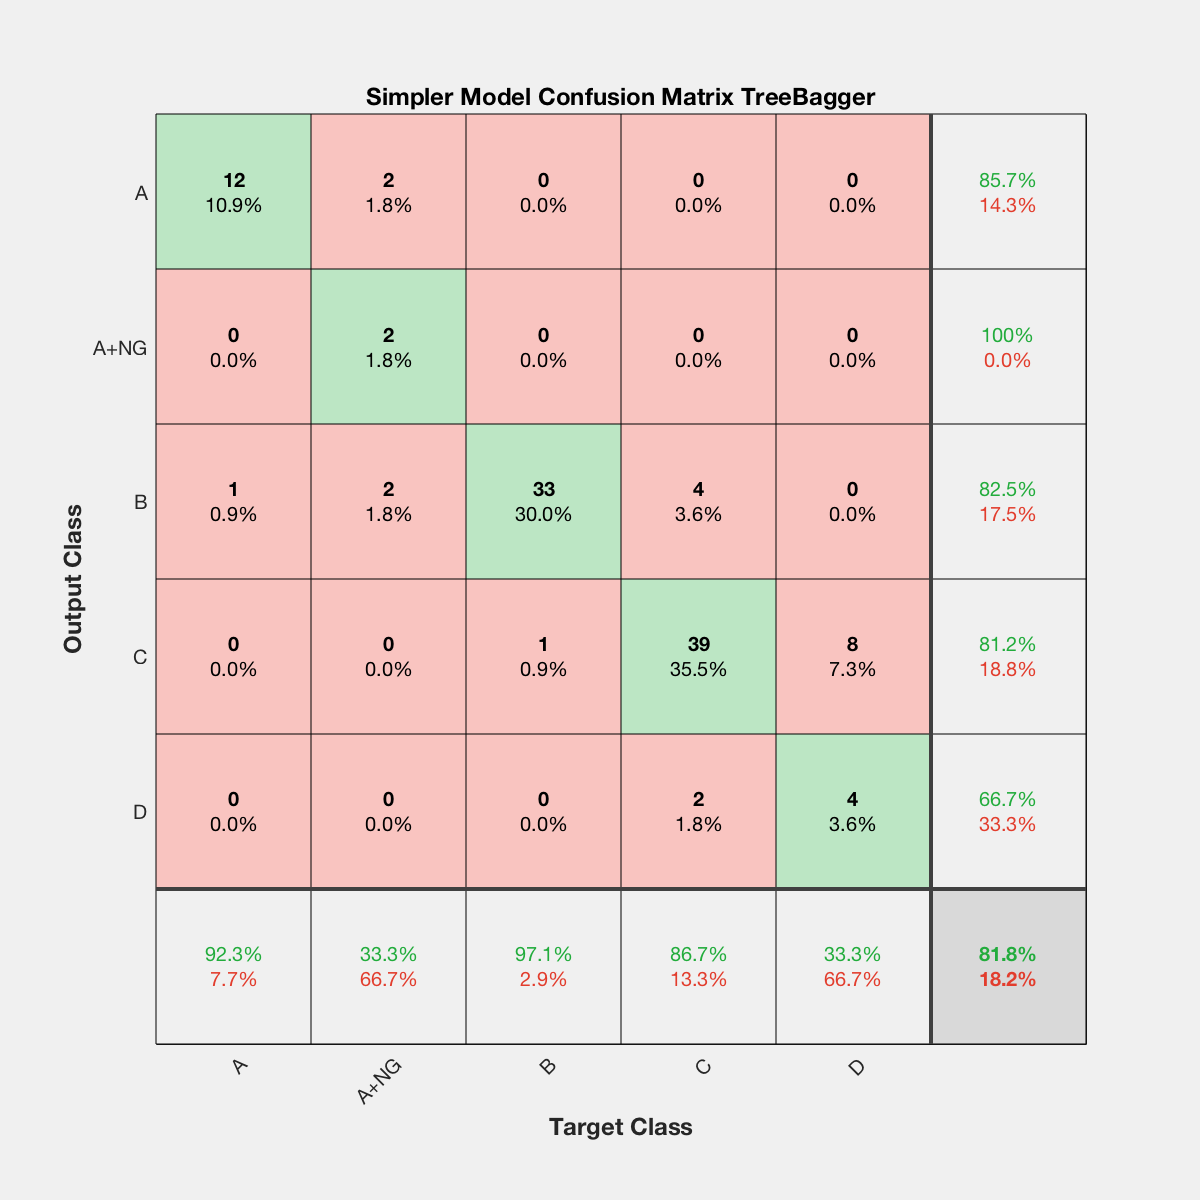

%--------------------------------------------------------------------------
% plot confusion matrix
figure
plotconfusion(categorical(nc_test.SPGGrade),categorical(outputs_simpler))
title('Simpler Model Confusion Matrix TreeBagger')
print('-dpng','NC-Simpler-TreeBagger-ConfusionMatrix.png');% save to an png file

% save the variable
% save TreeBaggerLearners
% ml_data_simple_tb = ml_data(:, isorted_imp(1:n))
% save TreeBagger_SimpleTB.mat ml_data_simple_tb